%% =========================================================================
% ANALISIS DE EFECTIVIDAD DEL CONTROLADOR PI (DATOS FISICOS)
% Archivo: PI_52kpa.csv (Salida de la ESP32)
% =========================================================================

clear; clc; close all;

%% 1. CONFIGURACIÓN
% Nombre del archivo CSV generado por la ESP32
nombreArchivo = 'PI_60kpa.csv'; 

% Referencia de Presión que usó en la ESP32
REFERENCIA_KPA = 58.0; % << AJUSTAR ESTE VALOR SI USÓ OTRA REFERENCIA EN LA ESP32 >>

% Especificaciones de Diseño Deseadas (para comparación)
ts_deseado = 1.0;   % Tiempo de asentamiento deseado (s)
Mp_deseado = 0.05;  % Sobreimpulso deseado (5% -> 0.05)


%% 2. CARGA DE DATOS
try
    % Carga el archivo CSV (asumiendo formato t_ms,PWM,Presion_kPa)
    data = readtable(nombreArchivo);
    
    t_ms = data.t_ms;
    u_pwm = data.PWM;
    p_kPa = data.Presion_kPa;
    
    t_s = t_ms / 1000.0; % Convertir tiempo a segundos
    
    fprintf('Datos cargados de "%s".\n', nombreArchivo);
catch
    error('ERROR: No se pudo cargar el archivo "%s". Asegúrese de que el nombre sea correcto.', nombreArchivo);
end

Datos cargados de "PI_60kpa.csv".



% ---

%% 3. SEGMENTACIÓN DEL TRAMO DE CONTROL
% Identificar el inicio del tramo de control (donde el PWM sale de 0)
pwm_threshold = 5;
idx_inicio_control = find(u_pwm > pwm_threshold, 1, 'first');

if isempty(idx_inicio_control)
    % Si no hay PWM alto, buscamos el inicio por un cambio brusco de presión
    idx_cambio = find(abs(diff(p_kPa)) > 0.1, 1, 'first');
    if isempty(idx_cambio)
        error('ERROR: No se detectó inicio de control activo (ni por PWM ni por cambio de presión).');
    end
    idx_inicio_control = idx_cambio;
end

% Recortar los datos para empezar justo antes del control (para un mejor stepinfo)
idx_inicio_analisis = max(1, idx_inicio_control - 100); % 100 muestras antes (1 segundo)
t_analisis = t_s(idx_inicio_analisis:end) - t_s(idx_inicio_analisis); % Tiempo re-ajustado a t=0
p_analisis = p_kPa(idx_inicio_analisis:end);
u_analisis = u_pwm(idx_inicio_analisis:end);

% Determinar el valor base (Presión en reposo)
P_BASE_KPA = mean(p_kPa(idx_inicio_analisis : idx_inicio_control - 1));
fprintf('Presión Base (antes del control): %.3f kPa\n', P_BASE_KPA);

Presión Base (antes del control): 3.310 kPa



% ---

%% 4. ANÁLISIS DE RENDIMIENTO (StepInfo CORREGIDO)

% Definimos el Umbral de Asentamiento (2%, que es 0.02)
UMBRAL_TS = 0.02; 

% 4.1. Usar stepinfo de MATLAB para calcular métricas
% CORRECCIÓN: Usamos 'SettlingThreshold' y 'InitialValue' para manejar el offset de CC.
try
    info = stepinfo(p_analisis, t_analisis, REFERENCIA_KPA, ...
                    'SettlingThreshold', UMBRAL_TS, ... % Resuelve el error de la función
                    'InitialValue', P_BASE_KPA);
    
    ts_real = info.SettlingTime;
    Mp_real = info.Overshoot;
    
    % ess se calcula manualmente (más robusto)
    P_FINAL = mean(p_analisis(end-100:end)); % Promedio de las últimas 100 muestras
    ess_real = REFERENCIA_KPA - P_FINAL; 

catch ME
    % Si falla, se muestra un warning, pero se calcula ess manualmente
    warning('StepInfo falló al calcular ts/Mp. Causa probable: Ruido excesivo o referencia no alcanzada. Mensaje: %s', ME.message);
    ts_real = NaN;
    Mp_real = NaN;
    P_FINAL = mean(p_analisis(end-100:end));
    ess_real = REFERENCIA_KPA - P_FINAL;
end

fprintf('\n--- RESULTADOS DEL CÁLCULO ---\n');


--- RESULTADOS DEL CÁLCULO ---


fprintf('Punto Inicial (P_BASE): %.3f kPa\n', P_BASE_KPA);

Punto Inicial (P_BASE): 3.310 kPa


fprintf('Punto Final (P_FINAL): %.3f kPa\n', P_FINAL);

Punto Final (P_FINAL): 57.338 kPa


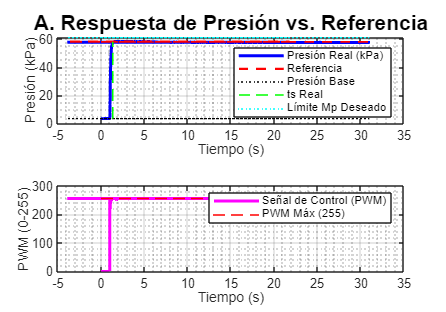


% ---

%% 5. VISUALIZACIÓN Y RESULTADOS

figure('Name', 'Analisis de Controlador PI Fisico', 'Color', 'w', 'Position', [100, 100, 1000, 700]);

% --- Subplot 1: Respuesta de Presión ---
subplot(2, 1, 1);
plot(t_analisis, p_analisis, 'b', 'LineWidth', 2, 'DisplayName', 'Presión Real (kPa)');
hold on;
plot(t_analisis, REFERENCIA_KPA*ones(size(t_analisis)), '--r', 'LineWidth', 1.5, 'DisplayName', 'Referencia');
plot(t_analisis, P_BASE_KPA*ones(size(t_analisis)), ':k', 'DisplayName', 'Presión Base');

% Límites de Desempeño
if ~isnan(ts_real)
    plot([ts_real, ts_real], [P_BASE_KPA, REFERENCIA_KPA], 'g--', 'LineWidth', 1, 'DisplayName', 'ts Real');
end
plot(t_analisis, REFERENCIA_KPA*(1 + Mp_deseado)*ones(size(t_analisis)), ':c', 'DisplayName', 'Límite Mp Deseado');

xlabel('Tiempo (s)'); ylabel('Presión (kPa)');
title('A. Respuesta de Presión vs. Referencia', 'FontSize', 14);
legend('show', 'Location', 'southeast');
grid on; grid minor;

% --- Subplot 2: Señal de Control (PWM) ---
subplot(2, 1, 2);
plot(t_analisis, u_analisis, 'm', 'LineWidth', 2, 'DisplayName', 'Señal de Control (PWM)');
hold on;
plot([0 max(t_analisis)], [255 255], '--r', 'DisplayName', 'PWM Máx (255)');
xlabel('Tiempo (s)'); ylabel('PWM (0-255)');
title('B. Señal de Control PWM Generada por el PI', 'FontSize', 14);
legend('show', 'Location', 'northeast');
grid on; grid minor;


fprintf('\n=== VALIDACIÓN DE DESEMPEÑO FISICO ===\n');


=== VALIDACIÓN DE DESEMPEÑO FISICO ===



% 5.1. Evaluación del Tiempo de Asentamiento
if ~isnan(ts_real)
    ts_status = condicional(ts_real <= ts_deseado);
    fprintf('ts Deseado: %.2f s | ts Real: %.4f s (%s)\n', ts_deseado, ts_real, ts_status);
else
    fprintf('ts Deseado: %.2f s | ts Real: No se pudo calcular.\n', ts_deseado);
end

ts Deseado: 1.00 s | ts Real: 1.3426 s (NO CUMPLE)



% 5.2. Evaluación del Sobreimpulso
if ~isnan(Mp_real)
    Mp_status = condicional(Mp_real <= Mp_deseado*100);
    fprintf('Mp Deseado: %.2f%% | Mp Real: %.4f%% (%s)\n', Mp_deseado*100, Mp_real, Mp_status);
else
    fprintf('Mp Deseado: %.2f%% | Mp Real: No se pudo calcular.\n', Mp_deseado*100);
end

Mp Deseado: 5.00% | Mp Real: 0.1190% (CUMPLE)



% 5.3. Evaluación del Error en Estado Estacionario
% Tolerancia práctica de 0.1 kPa 
ess_status = condicional(abs(ess_real) < 0.1); 
fprintf('ess Requerido: 0 | ess Real: %.4e kPa (%s)\n', ess_real, ess_status);

ess Requerido: 0 | ess Real: 6.6189e-01 kPa (NO CUMPLE)



fprintf('\n----------------------------------------------------\n');


----------------------------------------------------



% Función auxiliar para imprimir el estado CUMPLE/NO CUMPLE
function status = condicional(cond)
    if cond
        status = 'CUMPLE';
    else
        status = 'NO CUMPLE';
    end
end